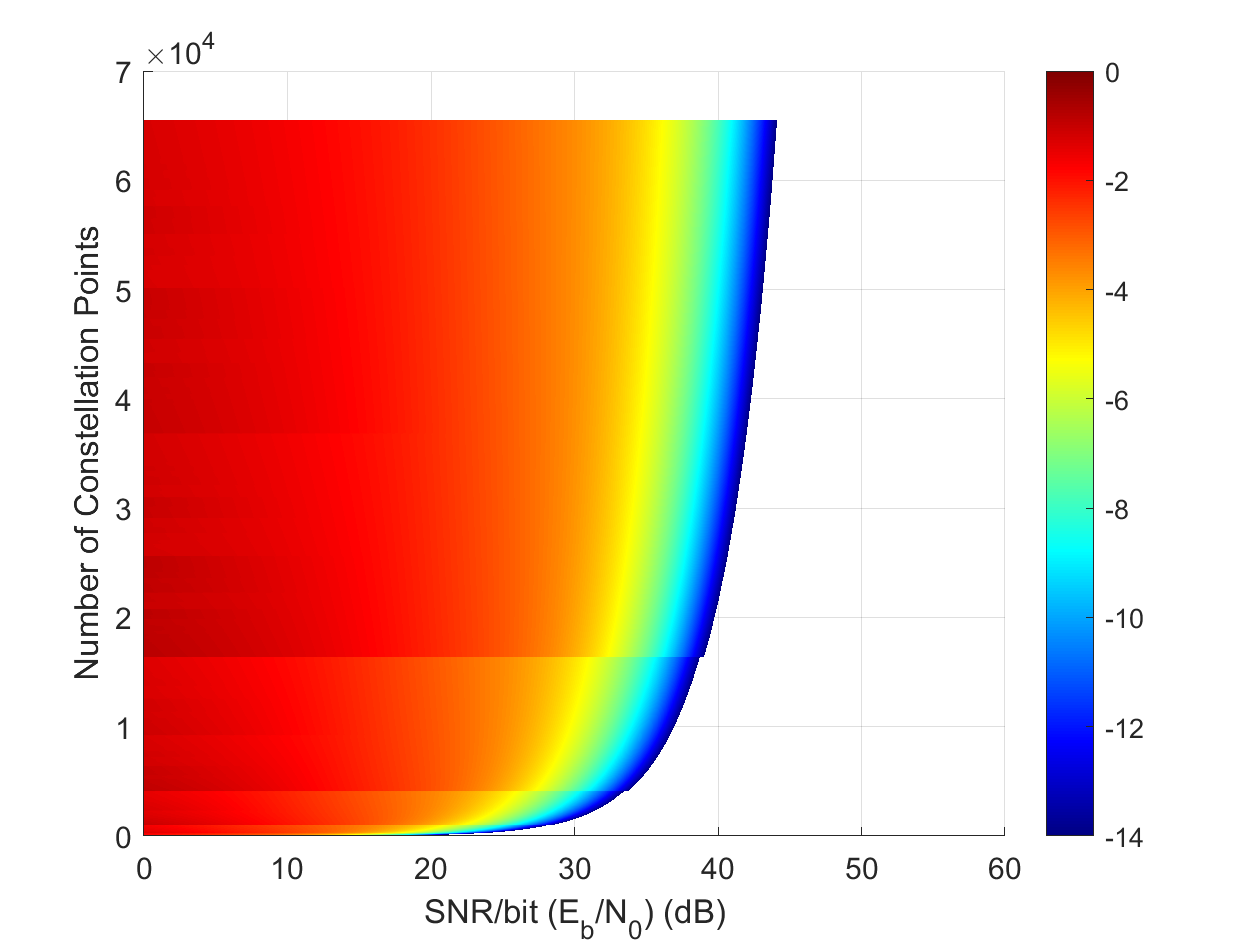


%r = Eb/N0
r = logspace(0,6,100);
%M = [4, 16, 64, 256, 1024, 4096];
M = linspace(2,4^8,1000);
M = round(M/2)*2;
L = length(M);

[r, M] = meshgrid(r,M);

legendText = {};
Pb = zeros(size(r));
for k = 1:L
    m = mean(M(k,:));
    Pb(k,:) = getPbQAM(m, r(k,:));
%     semilogy(10*log10(r(k,:)), Pb, 'LineWidth', 2)
%     grid on
%     hold on
%     legendText{k} = strcat(int2str(M(k)), 'QAM');
end

% legend(legendText)
% ylim([1e-14, 1e0])
% ylabel('Bit Error Rate (M-QAM)')
% xlabel('SNR/bit (E_b/N_0) (dB)')

surf(10*log10(r), log(M)/log(2), log(Pb), 'EdgeColor','none', 'FaceColor','interp')
zlabel('Bit Error Rate (M-QAM)')
xlabel('SNR/bit (E_b/N_0) (dB)')
ylabel('Number of Constellation Points')
grid on
colormap("jet")
c = colorbar()
% set(gca, 'zscale', 'log')
zlim([-14, 0])
% set(gca, 'ColorScale', 'log')
caxis([-14 0])
view(2)

ylabel(c, 'log(BER)')


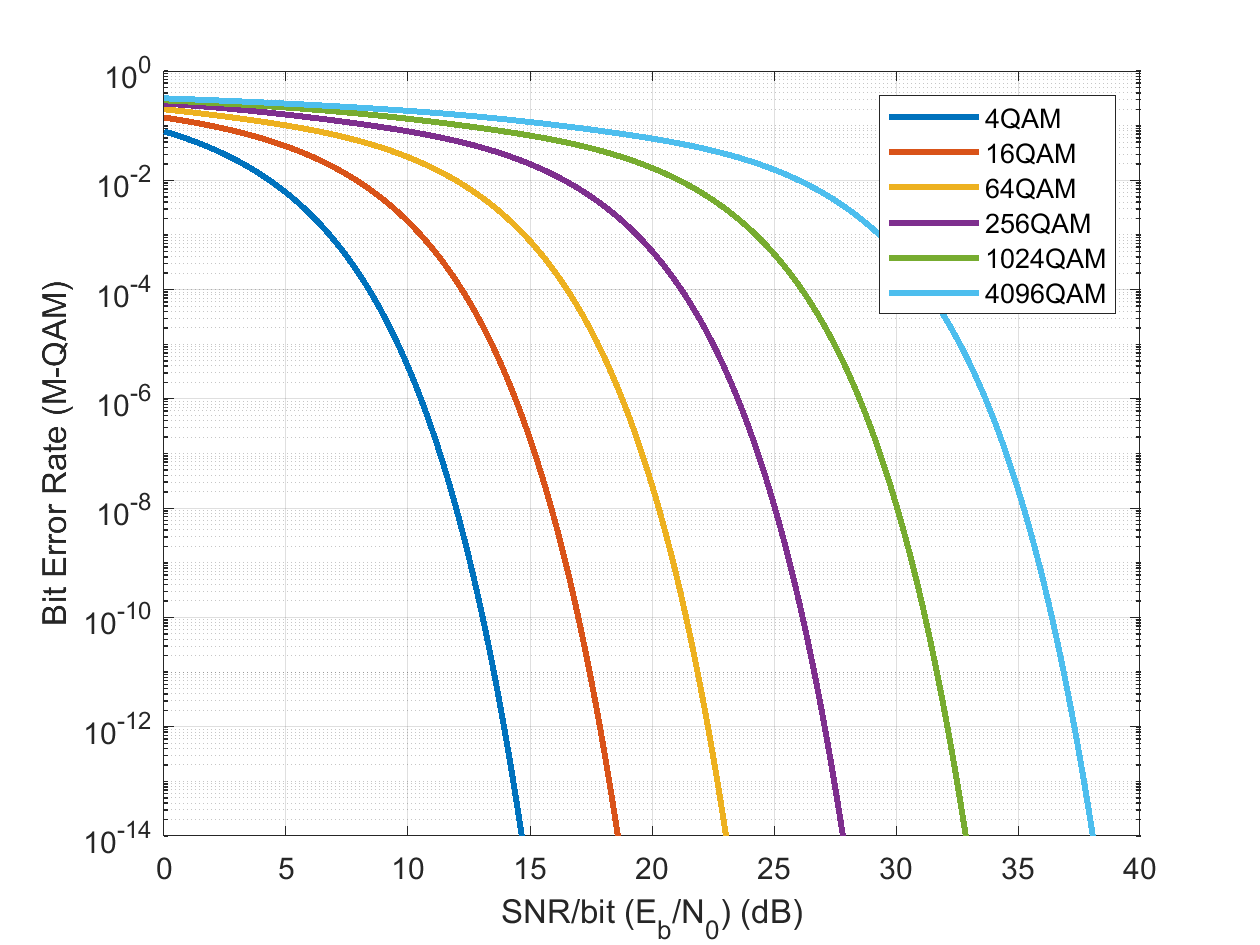


r = logspace(0,6,1000);
legendText = {};
% Pb2 = zeros(size(r));
m = [1, 2, 3, 4, 5, 6];
m = 4.^m;
for k = 1:length(m)
    Pb2 = getPbQAM(m(k), r); 
    semilogy(10*log10(r), Pb2, 'LineWidth', 2)
    grid on
    hold on
    legendText{k} = strcat(int2str(m(k)), 'QAM');
end
legend(legendText)
ylim([1e-14, 1e0])
ylabel('Bit Error Rate (M-QAM)')
xlabel('SNR/bit (E_b/N_0) (dB)')

function Pb = getPbQAM(M, r)
    sum = zeros(size(r));
    for k = 1:log2(sqrt(M))
        sum = sum + getQAMPbk(k, M, r);
    end
    Pb = sum/log2(sqrt(M));
end




function Pbk = getQAMPbk(k, M, r)
    topBound = (1 - 2^(-k))*sqrt(M) - 1;
    sum = zeros(size(r));
    for n = 0:topBound
        temp = n*2^(k-1);
        temp = temp/sqrt(M);
        temp = floor(temp);
        temp = (-1)^temp;
        
        temp2 = n*2^(k-1);
        temp2 = temp2/sqrt(M);
        temp2 = temp2 + 0.5;
        temp2 = floor(temp2);
        temp2 = 2^(k-1) - temp2;
        
        temp3 = 3*log2(M)/(2*(M-1));
        temp3 = temp3*r;
        temp3 = sqrt(temp3);
        temp3 = (2*n + 1)*temp3;
        temp3 = erfc(temp3);
        
        sum = sum + temp*temp2*temp3;
    end
    Pbk = sum/sqrt(M);
end